# `计算物理第一章作业`

`姓名：李哲   学号：1953946`

## `1、生成一个`$5 \times 5$`的幻方矩阵A，再做以下操作:`

n = 5;
A = magic(n)

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


#### `（1）选取矩阵A的上三角部分Au和下三角部分Al；`

 Au = triu(A)

Au =     17    24     1     8    15
     0     5     7    14    16
     0     0    13    20    22
     0     0     0    21     3
     0     0     0     0     9


 Al = tril(A)

Al =     17     0     0     0     0
    23     5     0     0     0
     4     6    13     0     0
    10    12    19    21     0
    11    18    25     2     9


#### `（2）求各列元素之和sum_c，各行元素之和sum_r；`

sum_c = sum(A)

sum_c =     65    65    65    65    65


sum_r = sum(A,2)

sum_r =     65
    65
    65
    65
    65


#### `（3）求各列元素平均值ave_c，各行元素平均值ave_r；`

ave_c = mean(A)

ave_c =     13    13    13    13    13


ave_r = mean(A,2)

ave_r =     13
    13
    13
    13
    13


#### `（4）求A的转置矩阵Z和由A对角元素构成的对角阵D；`

Z = transpose(A)

Z =     17    23     4    10    11
    24     5     6    12    18
     1     7    13    19    25
     8    14    20    21     2
    15    16    22     3     9


D = diag(diag(A))

D =     17     0     0     0     0
     0     5     0     0     0
     0     0    13     0     0
     0     0     0    21     0
     0     0     0     0     9


#### `（5）对A进行如下操作：左右翻转，上下翻转，旋转90度；`

flip_lr = fliplr(A)

flip_lr =     15     8     1    24    17
    16    14     7     5    23
    22    20    13     6     4
     3    21    19    12    10
     9     2    25    18    11


flip_ud = flipud(A)

flip_ud =     11    18    25     2     9
    10    12    19    21     3
     4     6    13    20    22
    23     5     7    14    16
    17    24     1     8    15


rot_90 = rot90(A)

rot_90 =     15    16    22     3     9
     8    14    20    21     2
     1     7    13    19    25
    24     5     6    12    18
    17    23     4    10    11


#### `（6）对A中各列元素升序排列，对A中所有元素构成的数组进行降序排列。`

sort_u = sort(A)

sort_u =      4     5     1     2     3
    10     6     7     8     9
    11    12    13    14    15
    17    18    19    20    16
    23    24    25    21    22


sort_d = transpose(sort(reshape(A,[],1),"descend"))

sort_d =     25    24    23    22    21    20    19    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1


## `2、求`$x=10,20,30,\dots,100$`时,`$y=x^2+\sin x+\log_{10} x$`的函数值，并绘出图形。`

#### `要求：`

#### `    （1）设置图名，坐标轴名，具体名称任意；`

#### `    （2）增加网格线，增加名称为function的图例（legend），并在图中加入注释（text命令，文字为`$y=x^2+\sin x+\log_{10}x$`，注意上下标的设置）；`

#### `    （3）函数曲线为红色点划线，数据点用圆点表示，线粗为2。`

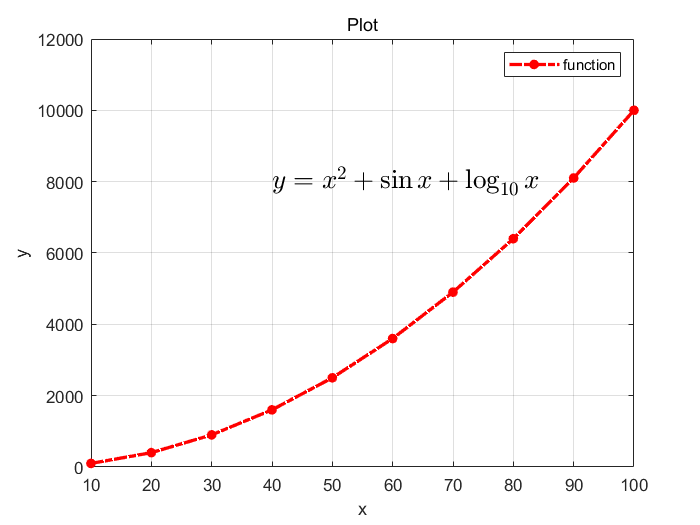

clear
x = 10:10:100;
y = x.^2 + sin(x) + log10(x);
p = plot(x,y,'r-..','DisplayName','function');
p.MarkerSize = 20;
p.LineWidth = 2;
title('Plot')
xlabel('x')
ylabel('y')
legend('function')
t = text(40,8000,'$y=x^{2}+\sin x+\log_{10} x$','FontSize',16);
t.Interpreter = "latex";
grid

y

y = 	1.0e+04 *

   0.010045597888911   0.040221397524639   0.090048908963063   0.160234717315181   0.250143659515063   0.360147334062928   0.490261898872157   0.640090920133307   0.810284823917304   1.000149363435889


## `3、画出曲面`$z=x^2y+\frac{\sqrt{y}}{x}$`在`$x\in \left[-5,5\right]$，$y\in\left[0,10\right]$`区域内的图像。`

#### `要求：`

#### `    （1）绘制三维曲面，并在二维平面内给出等高线（surfc命令）`

#### `    （2）视角设置为方位角60度，仰角30度。`

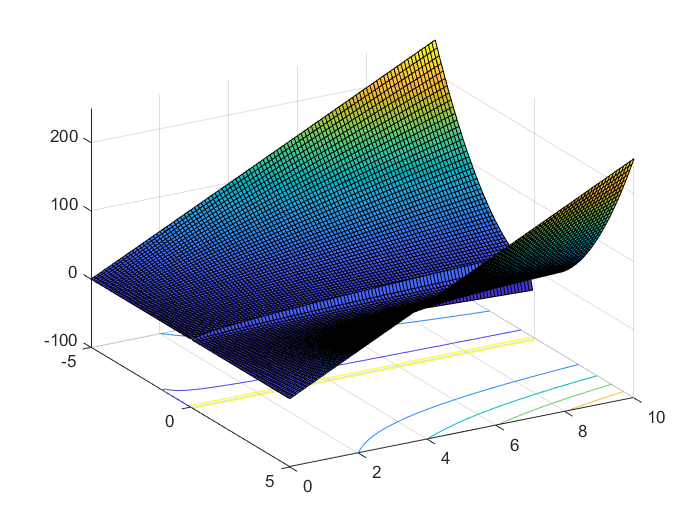

clear
[X,Y] = meshgrid(-5:0.1:5, 0:0.1:10);
Z = X.^2.*Y + sqrt(Y) ./ X;
S = surfc(X,Y,Z);
view(60,30);

## `4、编写百分制分数分等级程序，即`90-100`分为优秀，`80-89`分为良好，`70-79`分为中等，`60-69`分为及格，`60`分以下为不及格。`

#### `要求：`

#### `（1）使用条件判别和循环架构；`

#### `（2）可处理多个分数数据；`

#### `（3）对输入分数，以文本显示形式输出分数及其对应等级结果；`

#### `（4）对高于100分或低于0分的输入分数数据，提示错误信息，但程序继续运行处理后续分数。`

clear
grades = input('请输入成绩（在中括号中输入成绩，成绩之间以逗号隔开）：');
for i = 1:length(grades)
    if grades(i) < 0 || grades(i) >100
        disp('出现错误，输入的成绩必须大于0小于100')
    elseif grades(i) >= 0 && grades(i) <60
        disp([num2str(grades(i)),':成绩不及格'])
    elseif grades(i) >= 60 && grades(i) <= 100
        switch floor(grades(i)/10)
            case 6
                disp([num2str(grades(i)),':成绩及格'])
            case 7
                disp([num2str(grades(i)),':成绩中等'])
            case 8
                disp([num2str(grades(i)),':成绩良好'])
            otherwise
                disp([num2str(grades(i)),':成绩优秀'])
        end  
    end
end

## `选做题：绘制牛顿环的干涉图样。`

#### `要求：`

#### `（1）根据光学理论公式绘制，写出简要理论说明；`

#### `（2）程序可根据输入的光波波长，透镜曲率半径等相关参数给出干涉图样结果。`

#### `解：`

`    （1）理论说明：`

`        将一个曲率半径很大的凸透镜放置在一块玻璃板上，就可以通过它观察到一系列同心圆环组成的干涉条纹，这种条纹被称为牛顿环。`

`        光强公式为：`

## 
$$I=2I_0\sin^2(\frac{\pi r^2}{R\lambda})$$


`计算中取`$I_0=1$.

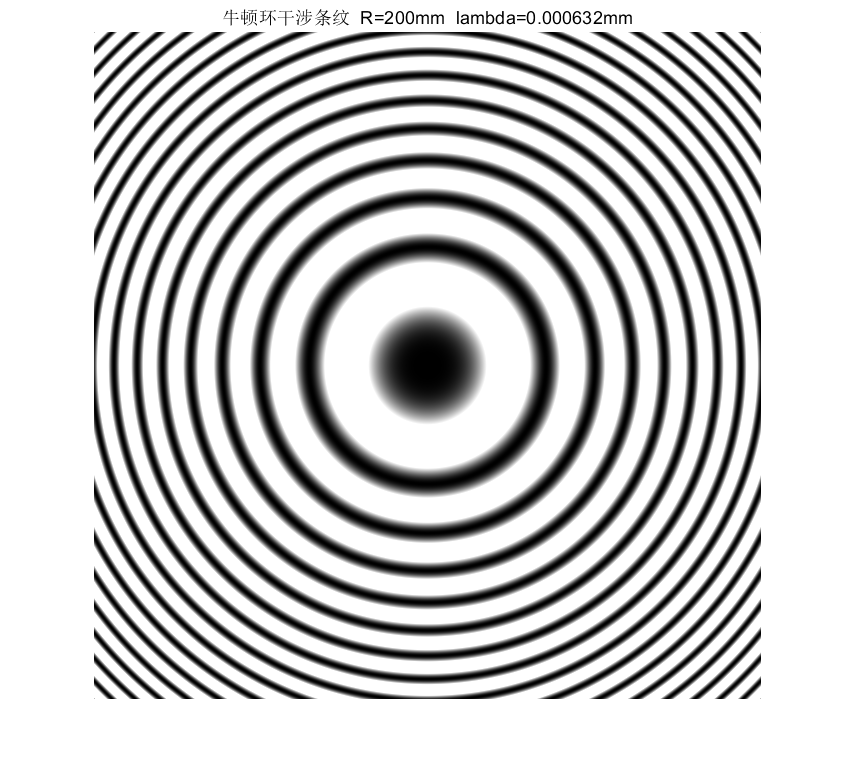

clear
lambda = input('请输入光波波长(mm):');
R = input('请输入透镜曲率半径(mm)：');
[X,Y] = meshgrid(-1:0.001:1, -1:0.001:1);
r = sqrt(X.^2+Y.^2);
I = 2*(sin((pi*r.^2)/(R*lambda))).^2;
figure
imshow(I)
title(['牛顿环干涉条纹  ','R=',num2str(R),'mm','  lambda=',num2str(lambda),'mm']);